## Load data

Directory = "D:\Neuropixel_SSD\Jon_BlenderClips-01_V1_PFC-12_g0\Jon_BlenderClips-01_V1_PFC-12_g0_imec0";
spikes = readNPY(fullfile(Directory,"Clean_Spikes/Clean_spike_times.npy"));
clusters = readNPY(fullfile(Directory,"Clean_Spikes/Clean_spike_clusters.npy"));
load(fullfile(Directory,"Clean_Spikes/Cell_QM.mat")); % Table with Quality metrics

## Cluster filtering

Clusters that do not pass the criteria

table_idx = Cell_QM.firing_rate < 0.1 | ...
    Cell_QM.Presence_ratio < 0.9 | ...
    Cell_QM.ISI_fraction > 0.01 | ...
    Cell_QM.ISI_fp > 0.5;

Eliminate low quality units

Cell_QM(table_idx,:) = [];
good_clusters = Cell_QM.ClusterID;

Clean clusters and spikes vectors from low quality units

spikes = spikes(ismember(clusters,good_clusters)); % first spikes vector!!
clusters = clusters(ismember(clusters,good_clusters));

## **Get Waveforms**

Completed 1 units of 89.
Completed 2 units of 89.
Completed 3 units of 89.
Completed 4 units of 89.
Completed 5 units of 89.
Completed 6 units of 89.
Completed 7 units of 89.
Completed 8 units of 89.
Completed 9 units of 89.
Completed 10 units of 89.
Completed 11 units of 89.
Completed 12 units of 89.
Completed 13 units of 89.
Completed 14 units of 89.
Completed 15 units of 89.
Completed 16 units of 89.
Completed 17 units of 89.
Completed 18 units of 89.
Completed 19 units of 89.
Completed 20 units of 89.
Completed 21 units of 89.
Completed 22 units of 89.
Completed 23 units of 89.
Completed 24 units of 89.
Completed 25 units of 89.
Completed 26 units of 89.
Completed 27 units of 89.
Completed 28 units of 89.
Completed 29 units of 89.
Completed 30 units of 89.
Completed 31 units of 89.
Completed 32 units of 89.
Completed 33 units of 89.
Completed 34 units of 89.
Completed 35 units of 89.
Completed 36 units of 89.
Completed 37 units of 89.
Completed 38 units of 89.
Completed 39 units of

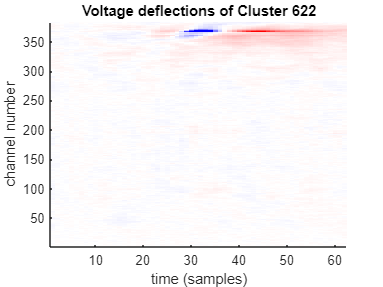

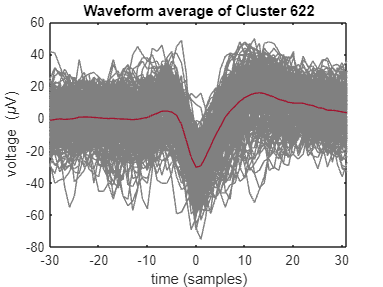

window = [-30,31];
number_of_waveforms = 1000;
sampling_frequency = 30000;
wf = clean_waveforms(Directory, spikes, clusters, window, number_of_waveforms,sampling_frequency);

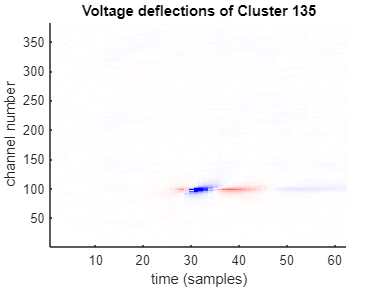

% Plot example
clu_of_int = 13; % cluster of interest 
figure; 
imagesc(squeeze(wf.waveFormsMean(clu_of_int,:,:)))
set(gca, 'YDir', 'normal'); xlabel('time (samples)'); ylabel('channel number'); 
colormap(colormap_BlueWhiteRed); caxis([-1 1]*max(abs(caxis()))/2); box off;
title(['Voltage deflections of Cluster ',num2str(good_clusters(clu_of_int))])

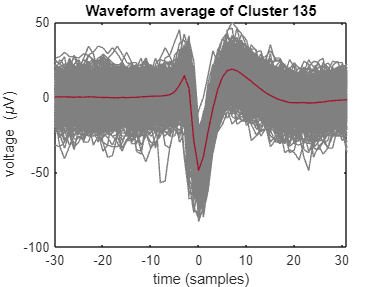

[y, idx] = max(max(abs(squeeze(wf.waveFormsMean(clu_of_int,:,:))),[],2));
x_axis = window(1):window(2);
figure
plot(x_axis, squeeze(wf.waveForms(clu_of_int,:,idx,:)),"Color",[0.5 0.5 0.5])
hold on
plot(x_axis, squeeze(wf.waveFormsMean(clu_of_int,idx,:)),"LineWidth",1);
xlim([window(1) window(2)]);
title(['Waveform average of Cluster ',num2str(good_clusters(clu_of_int))]);
xlabel('time (samples)'); ylabel('voltage (\muV)');
hold off

cluOfInt = 11;
binSize = 0.001;
CCG_duration = 2;
[a,y] = CCG(spikes(clusters == wf.unitIDs(cluOfInt)),ones(length(clusters(clusters == wf.unitIDs(cluOfInt))),1),'binsize',binSize,'duration',CCG_duration);

cluster11 = 1.0e+03 *

    0.0064
    0.0068
    0.0078
    0.0084
    0.0091
    0.0092
    0.0117
    0.0165
    0.0167
    0.0167


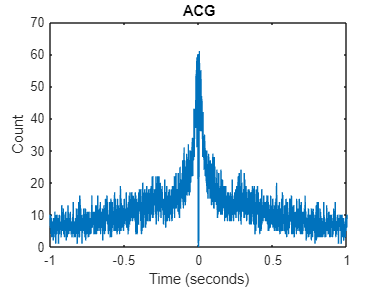


figure
plot(y,a), title('ACG'), xlabel('Time (seconds)'), ylabel('Count')